# Waveguides & optics scripts

In this document we provide scripts that perform computations related to the physics of optical waveguides, and other optics related phenomena. 

## Waveguide losses

According to reference material ([Large-scale broadband digital silicon photonic switches with vertical adiabatic couplers - Optica, 2016](http://dx.doi.org/10.1364/OPTICA.3.000064)) propagation loss is measured to be 1.1 dB/cm for this particular application. Furthermore, from literature ([Photonic Microsystems Micro and Nanotechnology Applied to Optical Devices and Systems-Springer (2008)](https://www.springer.com/gp/book/9780387290225)) we can also affirm that the bend loss is decreased to the point where it equals the waveguide propagation loss at a radius of around 10$\mu m$. Simulation and experimental results from the reference book, for varying radii and a bend of 90 deg are given below.

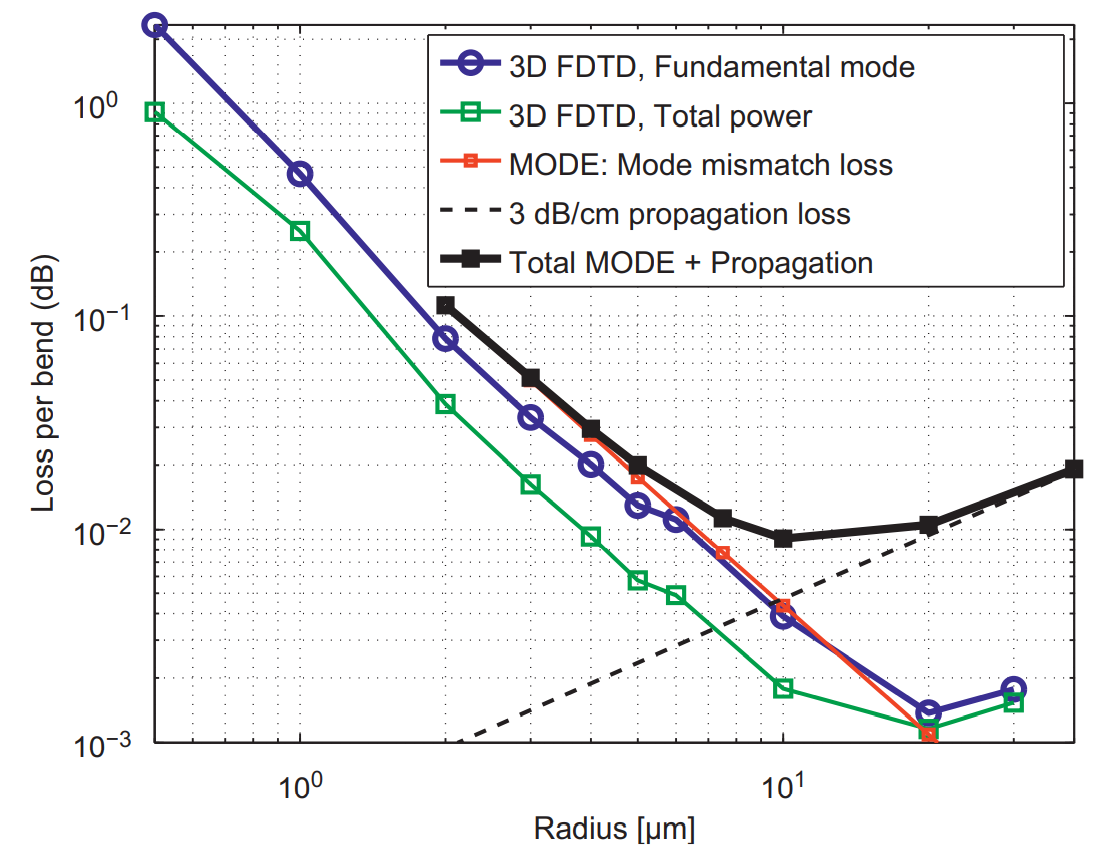

This in turn means that as long as we use bending radii greater than 10$\mu m$ we can assume that the bending losses are equivalent to the propragation losses. We will therefore take into account : 

- The distance covered by the light per cell. 2 paths are possible, we will consider them separetly. 

- For each bend that the light travels through, we will consider that for bends larger than 10$\mu m$ only propragation losses are considered.

# Linear coupler using 3rd degree Bézier curves segments

## Parametric curve computation

We will use 3 joint relaxed cubic bezier curves with 0 curvature at the end points, and matching curvature at the joint points. The curves are $P(t), Q(t), R(t)$, defined by control points $P,Q,R_{[0,1,2,3]}$ respectively.

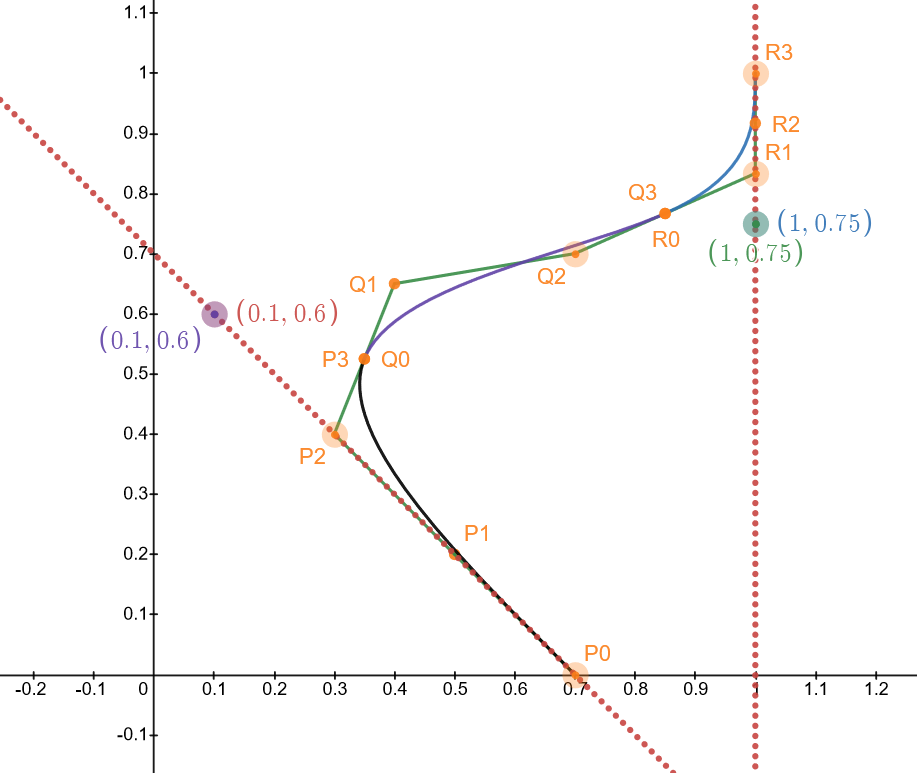

The curves need to respect the following parameters : 

- P0 is on the x-axis.

- R0 is on the vertical at x=1.

- P1 is the mid-point of [P2 , P0]

- P3 is the mid-point of [P2 , Q1]

- Q3 is the mid-point of [Q2, R1]

- R2 is the mid-point of [R1, R3]

- Apex A1+ of curve P must match the left apex A2- of curve Q.

- The right apex A2+ of curve Q must match the apex A3- of curve R.

close all;
clear variables;
%% Author : Claudio Jaramillo
% Using code written by Dr. Furci
% Created : 15.03.2021

%% Variables and magic numbers
%parameter t will be contained between 0 and 1
%concatenation of 3 B-splines 
%each spline is a 4-point relaxed bezier curve 
%for this section the spline is contained in the [1,1] square

%definition of waypoints coordinates
x_0 = 0.398; %0.4;
x_2 = -0.068665; %0.2;
x_12 = 0.566; %0.7;
y_12 = 0.7;%0.553;
y_21 = 0.8;%0.7863336;

%fixed waypoints (magic numbers)
y_0 = 0.0; %fixed
x_21 = 1; %fixed
x_23 = 1; %fixed
y_23 = 1; %fixed

%computation of dependent waypoint coordinates
x_1 = (x_2+x_0)/2;
y_2 = -x_2 + x_0;
y_1 = (y_2+y_0)/2;

x_11 = 2*x_12-1;
y_11 = 0.5*(-(3*x_12-2)+x_0+y_12);

x_3 = (x_2+x_11)/2;
y_3 = (y_2+y_11)/2;
x_10 = x_3;
y_10 = y_3;

x_13 = (x_12+x_21)/2;
y_13 = (y_12+y_21)/2;
x_20 = x_13;
y_20 = y_13;
x_22 = (x_21+x_23)/2;
y_22 = (y_21+y_23)/2;

%creation of structures
P.x = [x_0, x_1, x_2, x_3];
P.y = [y_0, y_1, y_2, y_3];

Q.x = [x_10, x_11, x_12, x_13];
Q.y = [y_10, y_11, y_12, y_13];

R.x = [x_20, x_21, x_22, x_23];
R.y = [y_20, y_21, y_22, y_23];

%scaling factor to match the required size of waveguide
%this affects the width of the waveguide, change accordingly 
scale_factor = 1; 


%% Point wise Bezier function
%point wise bezier function
%used for geometry plot & datapoint extraction
%data points will be extracted for t in [0,1]
%scaling will be done when extracting the points into the GDSII

step_counter = 1;
nb_of_points = 50;

bez_curve1_x = zeros(1, nb_of_points+1);
bez_curve1_y = zeros(1, nb_of_points+1);

bez_curve2_x = zeros(1, nb_of_points+1);
bez_curve2_y = zeros(1, nb_of_points+1);

bez_curve3_x = zeros(1, nb_of_points+1);
bez_curve3_y = zeros(1, nb_of_points+1);

for t=0:(1/nb_of_points):1
    %curve 1
    bez1_X = (1-t)*((1-t)*((1-t)*P.x(1)+t*P.x(2))+t*((1-t)*P.x(2)+t*P.x(3)))+...
        t*((1-t)*((1-t)*P.x(2)+t*P.x(3))+t*((1-t)*P.x(3)+t*P.x(4)));
    bez1_Y = (1-t)*((1-t)*((1-t)*P.y(1)+t*P.y(2))+t*((1-t)*P.y(2)+t*P.y(3)))+...
        t*((1-t)*((1-t)*P.y(2)+t*P.y(3))+t*((1-t)*P.y(3)+t*P.y(4)));
    
    bez_curve1_x(step_counter) = bez1_X;
    bez_curve1_y(step_counter) = bez1_Y;
    
    %curve 2
    bez2_X = (1-t)*((1-t)*((1-t)*Q.x(1)+t*Q.x(2))+t*((1-t)*Q.x(2)+t*Q.x(3)))+...
        t*((1-t)*((1-t)*Q.x(2)+t*Q.x(3))+t*((1-t)*Q.x(3)+t*Q.x(4)));
    bez2_Y = (1-t)*((1-t)*((1-t)*Q.y(1)+t*Q.y(2))+t*((1-t)*Q.y(2)+t*Q.y(3)))+...
        t*((1-t)*((1-t)*Q.y(2)+t*Q.y(3))+t*((1-t)*Q.y(3)+t*Q.y(4)));
    
    bez_curve2_x(step_counter) = bez2_X;
    bez_curve2_y(step_counter) = bez2_Y;
    
    %curve 3
    bez3_X = (1-t)*((1-t)*((1-t)*R.x(1)+t*R.x(2))+t*((1-t)*R.x(2)+t*R.x(3)))+...
        t*((1-t)*((1-t)*R.x(2)+t*R.x(3))+t*((1-t)*R.x(3)+t*R.x(4)));
    bez3_Y = (1-t)*((1-t)*((1-t)*R.y(1)+t*R.y(2))+t*((1-t)*R.y(2)+t*R.y(3)))+...
        t*((1-t)*((1-t)*R.y(2)+t*R.y(3))+t*((1-t)*R.y(3)+t*R.y(4)));
    
    bez_curve3_x(step_counter) = bez3_X;
    bez_curve3_y(step_counter) = bez3_Y;
    
    step_counter = step_counter+1;
    
    %clear
    clear bez1_X
    clear bez1_Y
    clear bez2_X
    clear bez2_Y
    clear bez3_X
    clear bez3_Y
end


%% Symbolic Bezier function
%Symbolic Bezier
%symbolic bezier functions
%symbolic computations

%in this section t is in [0,1]
syms t

%first segment
bez1_X = (1-t)*((1-t)*((1-t)*P.x(1)+t*P.x(2))+t*((1-t)*P.x(2)+t*P.x(3)))+...
    t*((1-t)*((1-t)*P.x(2)+t*P.x(3))+t*((1-t)*P.x(3)+t*P.x(4)));
bez1_X_diff1 = diff(bez1_X);
bez1_X_diff2 = diff(bez1_X,2);

bez1_Y = (1-t)*((1-t)*((1-t)*P.y(1)+t*P.y(2))+t*((1-t)*P.y(2)+t*P.y(3)))+...
    t*((1-t)*((1-t)*P.y(2)+t*P.y(3))+t*((1-t)*P.y(3)+t*P.y(4)));
bez1_Y_diff1 = diff(bez1_Y);
bez1_Y_diff2 = diff(bez1_Y,2);

%second segment
bez2_X = (1-t)*((1-t)*((1-t)*Q.x(1)+t*Q.x(2))+t*((1-t)*Q.x(2)+t*Q.x(3)))+...
    t*((1-t)*((1-t)*Q.x(2)+t*Q.x(3))+t*((1-t)*Q.x(3)+t*Q.x(4)));
bez2_X_diff1 = diff(bez2_X);
bez2_X_diff2 = diff(bez2_X,2);

bez2_Y = (1-t)*((1-t)*((1-t)*Q.y(1)+t*Q.y(2))+t*((1-t)*Q.y(2)+t*Q.y(3)))+...
    t*((1-t)*((1-t)*Q.y(2)+t*Q.y(3))+t*((1-t)*Q.y(3)+t*Q.y(4)));
bez2_Y_diff1 = diff(bez2_Y);
bez2_Y_diff2 = diff(bez2_Y,2);

%third segment
bez3_X = (1-t)*((1-t)*((1-t)*R.x(1)+t*R.x(2))+t*((1-t)*R.x(2)+t*R.x(3)))+...
    t*((1-t)*((1-t)*R.x(2)+t*R.x(3))+t*((1-t)*R.x(3)+t*R.x(4)));
bez3_X_diff1 = diff(bez3_X);
bez3_X_diff2 = diff(bez3_X,2);

bez3_Y = (1-t)*((1-t)*((1-t)*R.y(1)+t*R.y(2))+t*((1-t)*R.y(2)+t*R.y(3)))+...
    t*((1-t)*((1-t)*R.y(2)+t*R.y(3))+t*((1-t)*R.y(3)+t*R.y(4)));
bez3_Y_diff1 = diff(bez3_Y);
bez3_Y_diff2 = diff(bez3_Y,2);

%curvature computation per segment
curvature1 = (bez1_X_diff1*bez1_Y_diff2-bez1_X_diff2*bez1_Y_diff1)/...
    ((bez1_X_diff1)^2 + (bez1_Y_diff1)^2)^(3/2);
curvature2 = (bez2_X_diff1*bez2_Y_diff2-bez2_X_diff2*bez2_Y_diff1)/...
    ((bez2_X_diff1)^2 + (bez2_Y_diff1)^2)^(3/2);
curvature3 = (bez3_X_diff1*bez3_Y_diff2-bez3_X_diff2*bez3_Y_diff1)/...
    ((bez3_X_diff1)^2 + (bez3_Y_diff1)^2)^(3/2);


%% Checking the curvature boundary conditions(no scaling needed)
%checking the curvature continuity points
curv1_0 = subs(curvature1, 0);
curv2_0 = subs(curvature2, 0);
curv3_0 = subs(curvature3, 0);

curv1_1 = subs(curvature1, 1);
curv2_1 = subs(curvature2, 1);
curv3_1 = subs(curvature3, 1);

sprintf('curvature1 must be 0 at t=0 : %.4g',curv1_0)

ans = 'curvature1 must be 0 at t=0 : 2.086e-16'

sprintf('curvature1 at t=1 must equal curvature2 at t=0 : %.4g = %.4g ?',curv1_1,curv2_0)

ans = 'curvature1 at t=1 must equal curvature2 at t=0 : -9.265 = -9.265 ?'

sprintf('curvature2 at t=1 must equal curvature3 at t=0 : %.4g = %.4g ?',curv2_1,curv3_0)

ans = 'curvature2 at t=1 must equal curvature3 at t=0 : 1.31 = 1.31 ?'

sprintf('curvature3 must be 0 at t=1 : %.4g',curv3_1)

ans = 'curvature3 must be 0 at t=1 : 0'

%% Scaling

x_minrad = zeros(1,3);
y_minrad = [0,0,0];
scale_factor_loop = 1;

% disp(y_minrad(:)<5e-6)
% disp(any(y_minrad(:)<5e-6))

while any(y_minrad(:)<5) %5 in um
    
    %sclaing the symbolic funcs to compute the IRL curvature
    %the scaling law for curvature is 1/alpha
    curvature1_temp = curvature1/scale_factor_loop; %curvaturei is unscaled
    curvature2_temp = curvature2/scale_factor_loop;
    curvature3_temp = curvature3/scale_factor_loop;

    %curvature radius for extra data
    curvature_radius{1} = abs(1/curvature1_temp);
    curvature_radius{2} = abs(1/curvature2_temp);
    curvature_radius{3} = abs(1/curvature3_temp);

    %computing minimum radius per segment
    %func_seg = cell(3,1); %3 is a magic number (3 function pieces)

    for i=1:1:3
        [x_minrad(i), y_minrad(i)] = fminbnd(matlabFunction(curvature_radius{i}), 0, 1);
        disp(y_minrad(i))
    end

%     if y_minrad<5e-6
%         scale_factor = scale_factor_loop;
%         break;
%     end
    
    scale_factor = scale_factor_loop;
    scale_factor_loop = scale_factor_loop+1;
    
    clear curvature1_temp
    clear curvature2_temp
    clear curvature3_temp
    
end

    0.0941

    0.1080

    0.1508

    0.1881

    0.2159

    0.3017

    0.2822

    0.3239

    0.4525

    0.3763

    0.4318

    0.6033

    0.4703

    0.5398

    0.7541

    0.5644

    0.6478

    0.9050

    0.6585

    0.7557

    1.0558

    0.7525

    0.8637

    1.2066

    0.8466

    0.9716

    1.3574

    0.9407

    1.0796

    1.5083

    1.0347

    1.1876

    1.6591

    1.1288

    1.2955

    1.8099

    1.2229

    1.4035

    1.9608

    1.3169

    1.5114

    2.1116

    1.4110

    1.6194

    2.2624

    1.5051

    1.7274

    2.4132

    1.5991

    1.8353

    2.5641

    1.6932

    1.9433

    2.7149

    1.7873

    2.0512

    2.8657

    1.8813

    2.1592

    3.0165

    1.9754

    2.2672

    3.1674

    2.0695

    2.3751

    3.3182

    2.1635

    2.4831

    3.4690

    2.2576

    2.5910

    3.6198

    2.3517

    2.6990

    3.7707

    2.4457

    2.8070

    3.9215

    2.5398

    2.9149

    4.0723

    2.6339

    3.0229

    

%% Variable change for plotting
%change of variables on plots 2 and 3
%introduces a shift to the right to be able to stitch the plots
%this is only for plotting !!!!
syms t
%second segment (t-1)
bez2_X_plot = (1-(t-1))*((1-(t-1))*((1-(t-1))*Q.x(1)+(t-1)*Q.x(2))+(t-1)*((1-(t-1))*Q.x(2)+(t-1)*Q.x(3)))+...
    (t-1)*((1-(t-1))*((1-(t-1))*Q.x(2)+(t-1)*Q.x(3))+(t-1)*((1-(t-1))*Q.x(3)+(t-1)*Q.x(4)));
bez2_X_diff1_plot = diff(bez2_X_plot);
bez2_X_diff2_plot = diff(bez2_X_plot,2);

bez2_Y_plot = (1-(t-1))*((1-(t-1))*((1-(t-1))*Q.y(1)+(t-1)*Q.y(2))+(t-1)*((1-(t-1))*Q.y(2)+(t-1)*Q.y(3)))+...
    (t-1)*((1-(t-1))*((1-(t-1))*Q.y(2)+(t-1)*Q.y(3))+(t-1)*((1-(t-1))*Q.y(3)+(t-1)*Q.y(4)));
bez2_Y_diff1_plot = diff(bez2_Y_plot);
bez2_Y_diff2_plot = diff(bez2_Y_plot,2);

%third segment (t-2)
bez3_X_plot = (1-(t-2))*((1-(t-2))*((1-(t-2))*R.x(1)+(t-2)*R.x(2))+(t-2)*((1-(t-2))*R.x(2)+(t-2)*R.x(3)))+...
    (t-2)*((1-(t-2))*((1-(t-2))*R.x(2)+(t-2)*R.x(3))+(t-2)*((1-(t-2))*R.x(3)+(t-2)*R.x(4)));
bez3_X_diff1_plot = diff(bez3_X_plot);
bez3_X_diff2_plot = diff(bez3_X_plot,2);

bez3_Y_plot = (1-(t-2))*((1-(t-2))*((1-(t-2))*R.y(1)+(t-2)*R.y(2))+(t-2)*((1-(t-2))*R.y(2)+(t-2)*R.y(3)))+...
    (t-2)*((1-(t-2))*((1-(t-2))*R.y(2)+(t-2)*R.y(3))+(t-2)*((1-(t-2))*R.y(3)+(t-2)*R.y(4)));
bez3_Y_diff1_plot = diff(bez3_Y_plot);
bez3_Y_diff2_plot = diff(bez3_Y_plot,2);

%curvature computation per segment for plotting
curvature2_plot = (bez2_X_diff1_plot*bez2_Y_diff2_plot-bez2_X_diff2_plot*bez2_Y_diff1_plot)/...
    ((bez2_X_diff1_plot)^2 + (bez2_Y_diff1_plot)^2)^(3/2);
curvature3_plot = (bez3_X_diff1_plot*bez3_Y_diff2_plot-bez3_X_diff2_plot*bez3_Y_diff1_plot)/...
    ((bez3_X_diff1_plot)^2 + (bez3_Y_diff1_plot)^2)^(3/2);

%scaling of symbolic curvature for plotting
%disp(scale_factor)
curvature1_plot = curvature1/scale_factor;%curvature1 can be plotted directly
curvature2_plot = curvature2_plot/scale_factor;
curvature3_plot = curvature3_plot/scale_factor;

%symbolic radius of curvature for plotting
curvature_radius1_plot = abs(1/curvature1_plot);
curvature_radius2_plot = abs(1/curvature2_plot);
curvature_radius3_plot = abs(1/curvature3_plot);


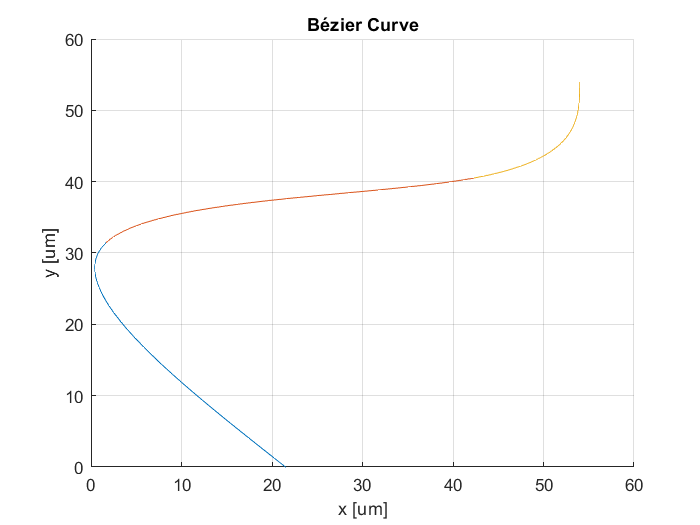

%% Bezier function plot
%plot the symbolic bezier function
f1 = figure;
hold on;

%we didn't change the variable for bez1 so we can just use the original
fplot(scale_factor*bez1_X, scale_factor*bez1_Y, [0 1])

fplot(scale_factor*bez2_X_plot,scale_factor*bez2_Y_plot, [1 2])

fplot(scale_factor*bez3_X_plot,scale_factor*bez3_Y_plot, [2 3])

%creation of the diagonal asymptote
% syms x;
% diagonal_asymp = scale_factor*(-x + x_0);
% 
% fplot(diagonal_asymp, [0 x_0], ':k')

hold off;

%params
title('Bézier Curve')
ylabel('y [um]')
xlabel('x [um]')
%xline(1,':k');
grid on;

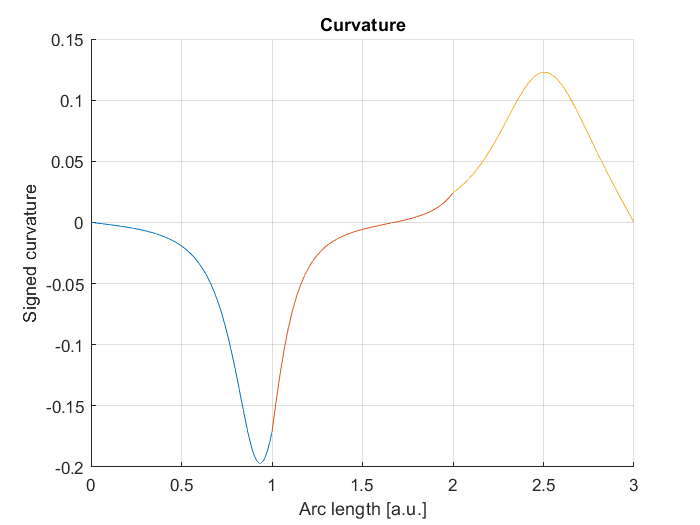

%% Curvature plot
%plot the symbolic curvature
syms t;

f2 = figure;
hold on;
%no change of variable for curvature 1, so we use the original
fplot(curvature1_plot, [0 1])

fplot(curvature2_plot, [1 2])

fplot(curvature3_plot, [2 3])
hold off;
%params
title('Curvature')
xlabel('Arc length [a.u.]')
ylabel('Signed curvature')
grid on;

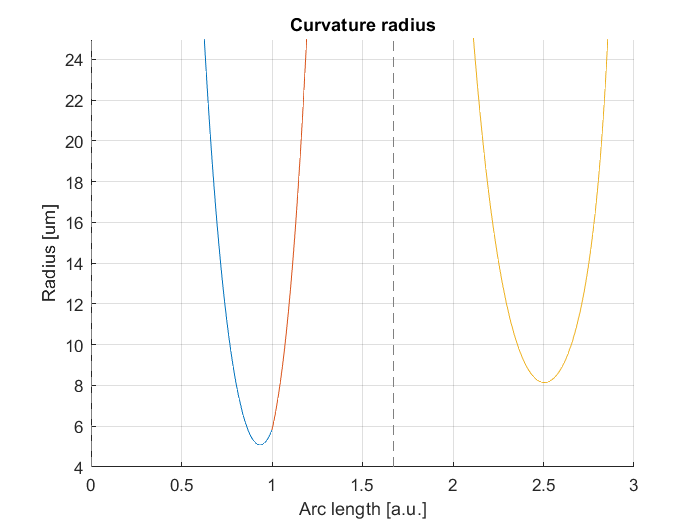

%% Radius of curvature plot
%plot the symbolic curvature
syms t;
f3 = figure;
hold on;
fplot(curvature_radius1_plot, [0 1])

fplot(curvature_radius2_plot, [1 2])

fplot(curvature_radius3_plot, [2 3])
hold off;

%params
title('Curvature radius')
xlabel('Arc length [a.u.]')
ylabel('Radius [um]')
ylim([4 25])
grid on;

%% Creating the GDSII file
% Written by Dr. Furci, modified by C. Jaramillo on the 07.04.2021
% use of wraith toolbox to generate GDSII file

write_dir = ['C:\Users\claud\Google Drive\EPFL\2. Master\MA2 - 2021\'...
    'MICRO-498 Semester Project\Design\Exports'];

%figure();
%layer 1
LayerStruct.layers(1)=1;
%1 corresponds to the GDSII layer number
LayerStruct.widths(1)=0.6; %in um

%layer 2
LayerStruct.layers(2)=3; %adding other layers
%3 corresponds to the GDSII layer number
LayerStruct.widths(2)=1.8; %adding other layers

StructCode='BezierBottomWaveguide180_0p6';
BendLib=Raith_library('BezierCurve');

x = scale_factor*[bez_curve1_x bez_curve2_x bez_curve3_x];
y = scale_factor*[bez_curve1_y bez_curve2_y bez_curve3_y];

path = [x;y];

for e=1:numel(LayerStruct.layers)
    layer=LayerStruct.layers(e);
    width=LayerStruct.widths(e); 
    BendVector(e)=Raith_element('path',layer,path,width,layer/8*1.5);
end

StrName=[StructCode sprintf('BezierCurve')];
BendStruct=Raith_structure(StrName,BendVector);
BendLib.append(BendStruct);
BendLib.writegds(write_dir,'plain');


Checking for missing structures...OK.
Writing C:\Users\claud\Google Drive\EPFL\2. Master\MA2 - 2021\MICRO-498 Semester Project\Design\Exports\BezierCurve.gds...
     Header information
     Structure 1/1:  BezierBottomWaveguide180_0p6BezierCurve
GDSII library BezierCurve.csf successfully written.



# Alternative coupler design using sigmoid function

close all;
%clear variables;

%% Variables and magic numbers
a = 39.607 ; %height of sigmoid function 
b = 0.2 ;%slope
length_coupler = 40;

step_counter = 1;
nb_of_points = 100;

%% point wise sigmoid function for data extraction
x_space = linspace(-length_coupler,length_coupler,nb_of_points+1);
sigmoid_y = zeros(1, nb_of_points+1);

%% Computing the curvature
sigmoid_diff_y = zeros(1, nb_of_points+1);
sigmoid_diff2_y = zeros(1, nb_of_points+1);
curvature_y = zeros(1,nb_of_points+1);

for i=1:1:nb_of_points
    sigmoid_y(i) = logistic_func(x_space(i),a,b);
    sigmoid_diff_y(i) = logistic_func(x_space(i),a,b) * (1-logistic_func(x_space(i),a,b));
    sigmoid_diff2_y(i) = logistic_func(x_space(i),a,b)*(1-logistic_func(x_space(i),a,b))^2 - sigmoid_diff_y(i);
    curvature_y(i) = sigmoid_diff2_y(i)./((1+sigmoid_diff_y(i)^2)^(3/2));
end

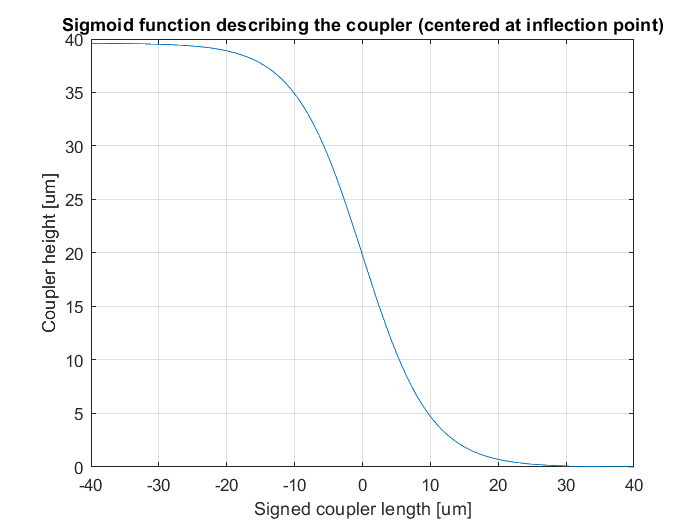

%% Sigmoid func plot
figure_sigmoid = figure();

plot(x_space,sigmoid_y)

%params
title('Sigmoid function describing the coupler (centered at inflection point)')
xlabel('Signed coupler length [um]')
ylabel('Coupler height [um]')
grid on;

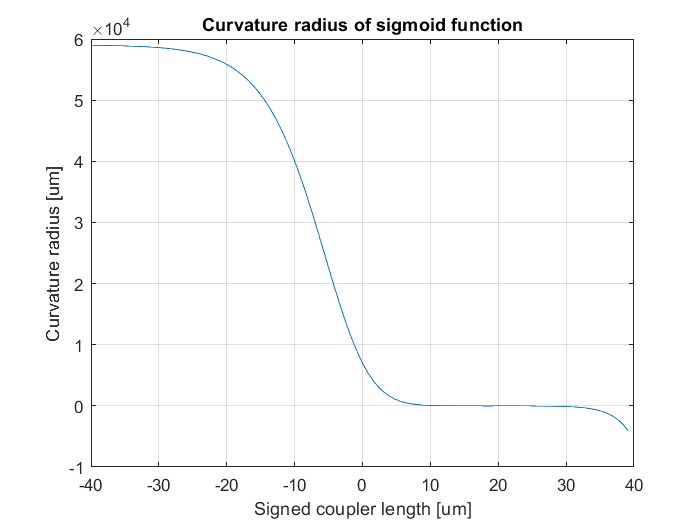


%%curvature radius func plot
figure_sigmoid_curvature = figure();

plot(x_space,(1./curvature_y));

%params
title('Curvature radius of sigmoid function')
xlabel('Signed coupler length [um]')
ylabel('Curvature radius [um]')
grid on;

%% Creating the GDSII file
%use of wraith toolbox to generate GDSII file

write_dir = ['C:\Users\claud\Google Drive\EPFL\2. Master\MA2 - 2021\'...
    'MICRO-498 Semester Project\Design\Exports\GDS'];

%figure();
%layer 1
LayerStruct.layers(1)=1;
%1 corresponds to the GDSII layer number
LayerStruct.widths(1)=1; %in um

%layer 2
LayerStruct.layers(2)=3; %adding other layers
%3 corresponds to the GDSII layer number
LayerStruct.widths(2)=4; %adding other layers

StructCode='SigmoidCoupler';
BendLib=Raith_library('SigmoidCoupler');

x = x_space;
y = sigmoid_y;

path = [x;y];

for e=1:numel(LayerStruct.layers)
    layer=LayerStruct.layers(e);
    width=LayerStruct.widths(e); 
    BendVector(e)=Raith_element('path',layer,path,width,layer/8*1.5);
end

StrName=[StructCode sprintf('SigmoidCoupler')];
BendStruct=Raith_structure(StrName,BendVector);
BendLib.append(BendStruct);
BendLib.writegds(write_dir,'plain');


Checking for missing structures...OK.
Writing C:\Users\claud\Google Drive\EPFL\2. Master\MA2 - 2021\MICRO-498 Semester Project\Design\Exports\GDS\SigmoidCoupler.gds...
     Header information
     Structure 1/1:  SigmoidCouplerSigmoidCoupler
GDSII library SigmoidCoupler.csf successfully written.



# Computation of estimated optical losses

We compute the propagation losses as : 


$$Loss_{Total} = L_{straight} \cdot PropLoss + L_{curve} \cdot BendLoss + LowCrossingLoss$$


## Linear coupler - Design 4 : Bezier curve

%% Computation of lengths

% Computation of total arc length of Bezier polygon
% We will compute the arc length of each of the 3 segments separetly and
% then add them together. We will use the SCALED value, naturally. 

syms t
%we are using the non-shifted curves and integrate from 0 to 1
%the length is scaled by multiplying the curve by scale factor
%t remians between 0 and 1

%lengths in um !

integrand_curve1 = scale_factor*sqrt((bez1_X_diff1)^2 + (bez1_Y_diff1)^2);
integrand_curve2 = scale_factor*sqrt((bez2_X_diff1)^2 + (bez2_Y_diff1)^2);
integrand_curve3 = scale_factor*sqrt((bez3_X_diff1)^2 + (bez3_Y_diff1)^2);

L_1 = vpa(int(integrand_curve1, [0 1]));
L_2 = vpa(int(integrand_curve2, [0 1]));
L_3 = vpa(int(integrand_curve3, [0 1]));

L_total = L_1+L_2+L_3;

% finding the t values for which the radius is larger than 15 um
% these values are found 
t_curve1 = vpasolve(curvature_radius1_plot==15,t,[0 1]);
t_curve2 = vpasolve(curvature_radius2_plot==15,t,[1 2]);
t_curve3a = vpasolve(curvature_radius3_plot==15,t, 2.2); %first sol
t_curve3b = vpasolve(curvature_radius3_plot==15,t, 2.7); %second sol

%finding the ''straight'' length, since we're using the non-shifted curves
%we need to correct the boundary values 
L_straight1 = vpa(int(integrand_curve1, [0 t_curve1]));
L_straight2 = vpa(int(integrand_curve2, [(t_curve2-1) 1]));
L_straight3 = vpa(int(integrand_curve3, [0 (t_curve3a-2)]));
L_straight4 = vpa(int(integrand_curve3, [(t_curve3b-2) 1]));

L_straight_bezier = L_straight4+L_straight3+L_straight2+L_straight1;

%finding the bend length at r=5
L_bend_5 = vpa(int(integrand_curve1, [t_curve1 1])) + ...
    vpa(int(integrand_curve2, [0 t_curve2-1]));

%finding the bend length at r=8
L_bend_8 = vpa(int(integrand_curve3, [t_curve3a-2 t_curve3b-2]));

%% Computation of losses
% we will use certain values found in literature 

prop_loss = 1.6; %[dB/cm], from Dr. Furci's research
loss_R5 = 0.5e-2; %[dB/90deg bend] at 5 um, from literature
loss_R8 = 7e-3; %[dB/90deg bend] at 8 um, from literature
low_loss_crossing =  0.011; %low loss crossing losses, from research

total_loss_bezier = vpa((L_straight_bezier/10000)*prop_loss + loss_R5*0.5 + loss_R8 + low_loss_crossing)

$$total\_loss\_bezier = 0.033492801310795165844777471455036$$

## Linear coupler - Design 6 : Sine-Circle-Sine 

%% Computation of lengths 
% lengths in um
%we approximate the sine-circ-sine bends to a circle, and we don't take
%into account the losses from mode matching
L_straight_sinecircsine = 0.997+9.651+32.260+8.830+11.760; %different straight segments
L_bend_R8 = 2.356*8; %2.356 rad corresponds to 135 deg bend
L_bend_R5 = pi/2*5; %90 deg bend

total_loss_sinecircsine = loss_R5+1.5*loss_R8+(L_straight_sinecircsine/10000)*prop_loss+low_loss_crossing

total_loss_sinecircsine = 0.0367

## U-Turn coupler - Design 1

%we approyimate the large radius u-turn by a circle, and compute the
%losses using propagation losses because the radius is large (15 um)

L_straight_uturn = 76.759+61.366;
L_ubend_R15 = pi*15; %180 deg turn
L_Lbend_R15 = pi/2*15; %90 deg turn

total_loss_uturn = loss_R5+((L_straight_uturn+L_ubend_R15+L_Lbend_R15)/10000)*prop_loss

total_loss_uturn = 0.0384

function [y1] = logistic_func(x1,a,b)
    y1 = a ./ (1+exp(b*x1));
end